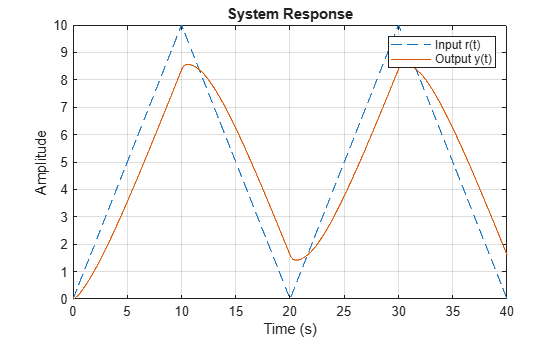

G = tf([75 75], [1 30 200 75]);

t = (0:0.01:40)';

r = zeros(size(t));

for i = 1:length(t)

    if t(i) <= 10
        r(i) = t(i);

    elseif t(i) <= 20
        r(i) = 20 - t(i);

    elseif t(i) <= 30
        r(i) = t(i) - 20;

    else
        r(i) = 40 - t(i);
    end

end

y = lsim(G, r, t);

figure
plot(t, r, '--')
hold on
plot(t, y)
grid on
legend('Input r(t)', 'Output y(t)')
xlabel('Time (s)')
ylabel('Amplitude')
title('System Response')
hold off

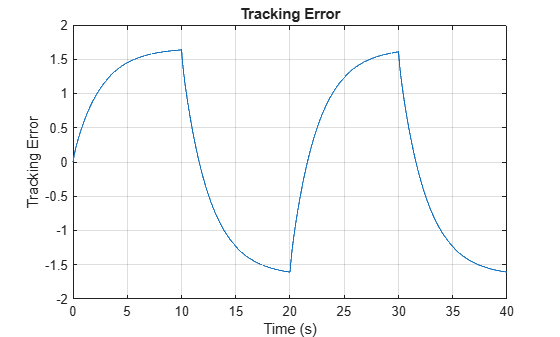


err = r - y;

figure
plot(t, err)
grid on
xlabel('Time (s)')
ylabel('Tracking Error')
title('Tracking Error')